Universidad de Costa Rica

Maestría de Computación e Informática

Elaborado por Ruth Campos

Fecha: 11/09/2024

Ejercicios en Clase 5:  Notas

clear all
clc
clf


ts = 100 %numero de muestras

ts = 100

T = 10 % tiempo total

T = 10

dt = T/ts; % dt = 0.1 %s
% ts = T/dt
%t = linspace(0 , 10, 100)
t = [0:dt:(T-dt)] % segundos

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


psi = linspace(0 , 0, 100)

psi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%psi_cmd = ones(size(t))
%psi_cmd = zeros(size(t))

psi(:,31:40) = 0.5 % rad/s

psi =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0


psi(:,51:60) = -0.5 % rad/s

psi =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000         0         0         0         0         0         0         0         0         0         0


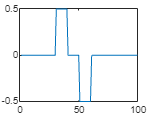

plot(psi)


v = 1 % 1m/s

v = 1

L = 1 % m

L = 1

thetad = v/L * tan(psi) % velocidad angular

thetad =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463         0         0         0         0         0         0         0         0         0         0


theta = cumtrapz(thetad)*dt

theta =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0273    0.0819    0.1366    0.1912    0.2458    0.3005    0.3551    0.4097    0.4644    0.5190    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463    0.5463


xd = v*cos(theta) % velocidad x

xd =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9996    0.9966    0.9907    0.9818    0.9699    0.9552    0.9376    0.9172    0.8941    0.8683    0.8545    0.8545    0.8545    0.8545    0.8545    0.8545    0.8545    0.8545    0.8545    0.8545


yd = v*sin(theta) % velocidad y

yd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0273    0.0819    0.1362    0.1900    0.2434    0.2960    0.3477    0.3984    0.4478    0.4960    0.5195    0.5195    0.5195    0.5195    0.5195    0.5195    0.5195    0.5195    0.5195    0.5195



% integrando
x = cumtrapz(xd*dt)

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.0998    3.1992    3.2978    3.3954    3.4916    3.5863    3.6790    3.7696    3.8577    3.9438    4.0293    4.1147    4.2002    4.2856    4.3711    4.4565    4.5420    4.6274    4.7128


y = cumtrapz(yd*dt)

y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0014    0.0068    0.0177    0.0340    0.0557    0.0827    0.1149    0.1522    0.1945    0.2417    0.2924    0.3444    0.3963    0.4483    0.5002    0.5522    0.6042    0.6561    0.7081    0.7600


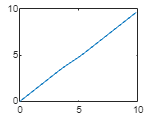

plot(t, x')

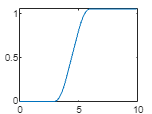

plot(t, y')

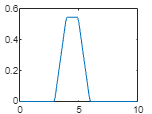

plot(t, theta')

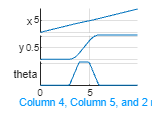



stackedplot(t, [x' y' theta' psi' xd' yd' thetad'], DisplayLabels=["x" "y" "theta" "psi" "xd" "yd" "thetad"])

grid on

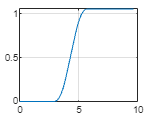

plot(x,y)
grid on

### 4.1.1 Car-Like Mobile Robots

sl_lanechange
out = sim("sl_lanechange")

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


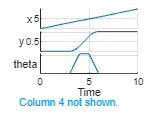

t = out.get("t");
q = out.get("y");
stackedplot(t,q, ...
  DisplayLabels=["x","y","theta","psi","xd","yd", "thetad"], ...

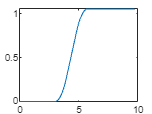

  GridVisible=1,XLabel="Time")
plot(q(:,1),q(:,2))

#### 4.1.1.1 Driving to a Point

sl_drivepoint
xg = [5 5];
% x0 = [8 5 pi/2];
x0 = [9 9 0];
pause(1);
r = sim("sl_drivepoint");
q = r.find("y");
plot(q(:,1),q(:,2));


#### 4.1.1.2 Driving Along a Line

sl_driveline
L = [1 -2 4];
xg = [5 5];
x0 = [8 5 pi/2];
pause(1);
r = sim("sl_driveline");
q = r.find("y");
plot(q(:,1),q(:,2));

